# Hippocampus 

subject ='Group';
plot_window=[1 25 1920 1080];
home_dir = '/bigvault/Projects/seeg_pointing';
group_dir = '/bigvault/Projects/seeg_pointing/results/memory_group/';

% obj_pic = 51:165; % original [-2,3], save [-0.5,1.5], pic [0,1.15]
% seq_pic = 251:500;% original [-5,7], save [-2.5,5], pic [0,2.5]
% seq_pre = 1:200;  % original [-5,7], save [-2.5,5], pre interval [-2.5,-0.5]
% seq_after = 501:700;% original [-5,7], save [-2.5,5], pre interval [2.5,4.5]

index = [7,13,25,31,43,49];
bd_id = [index,index+18*6]; 
non_bd_id = [index+18*3,index+18*9]; 

% load wavlet data for subject
data1 = load_mat([group_dir,'wavelet/wavele_bd.mat']);
data2 = load_mat([group_dir,'wavelet/wavele_non_bd.mat']);

### Boundary turns vs nonBoundary turns

#### total

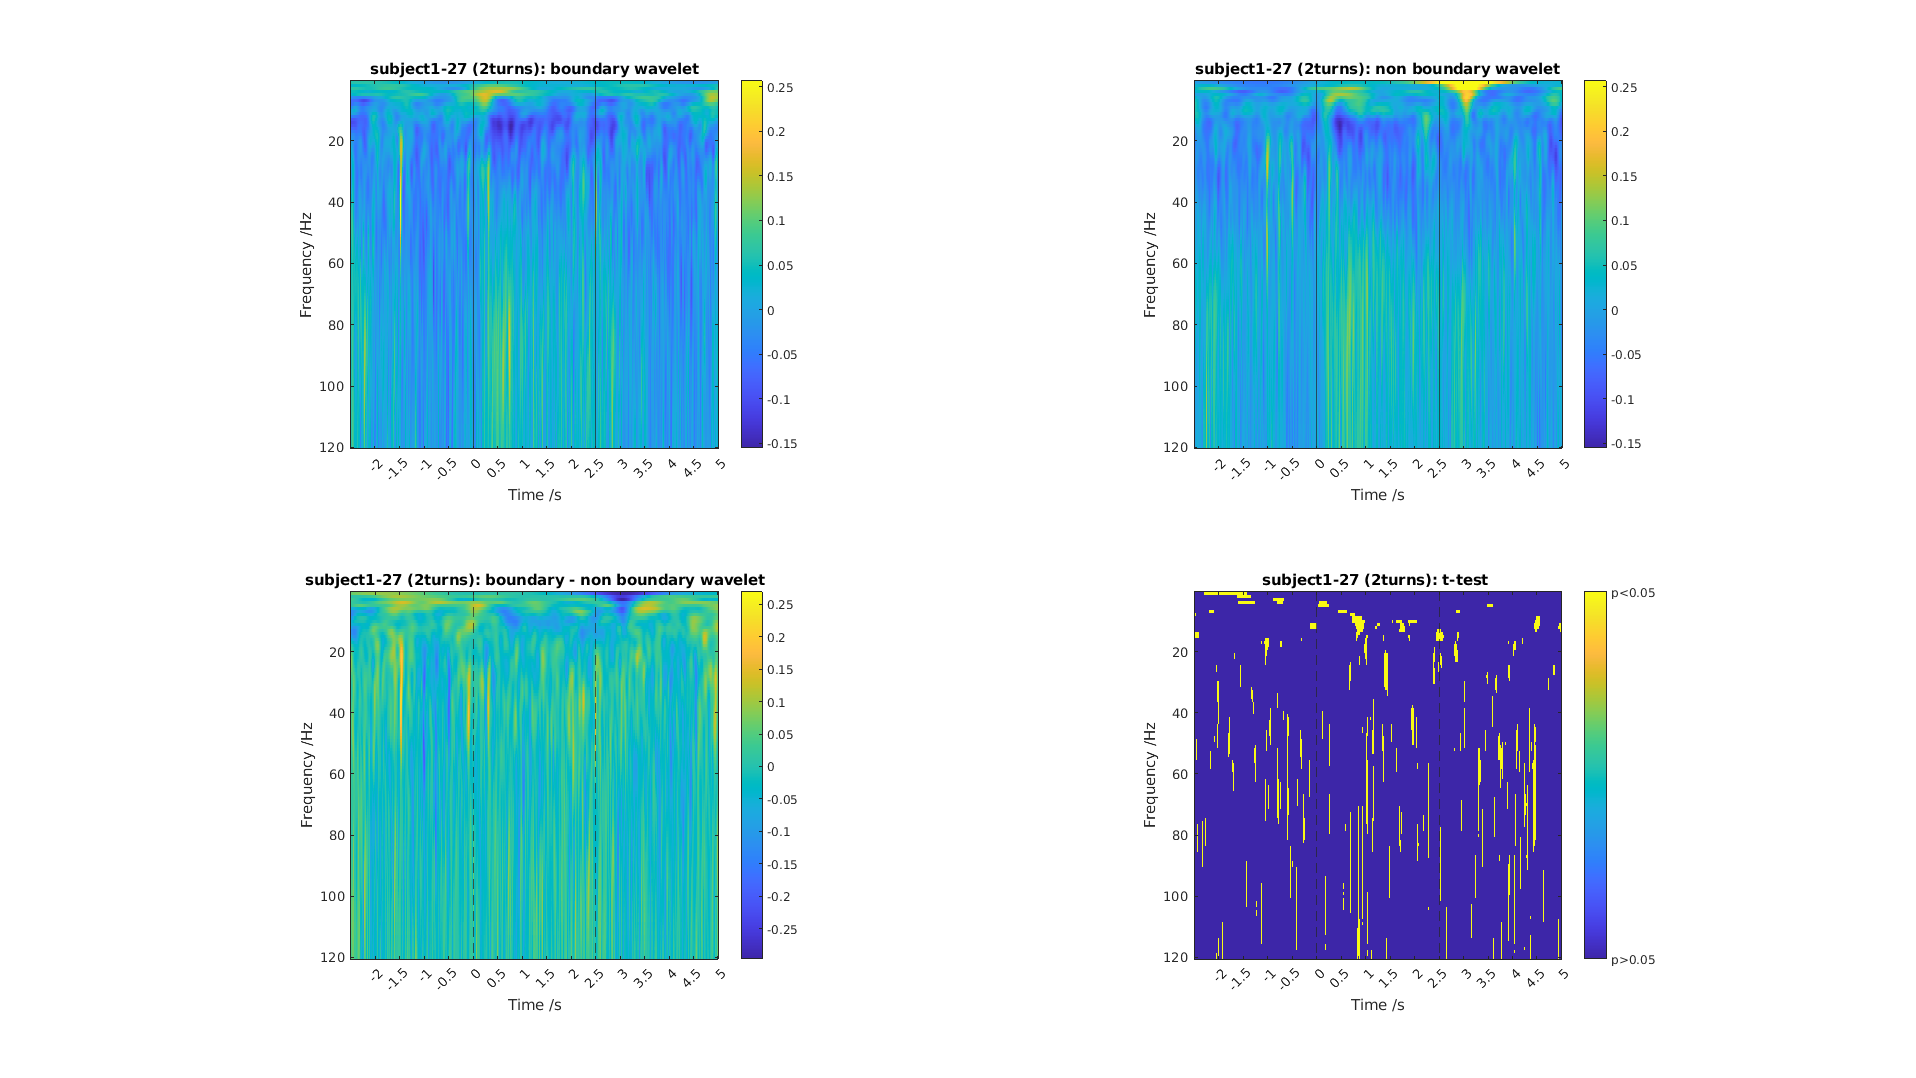

Elapsed time is 143.053431 seconds.


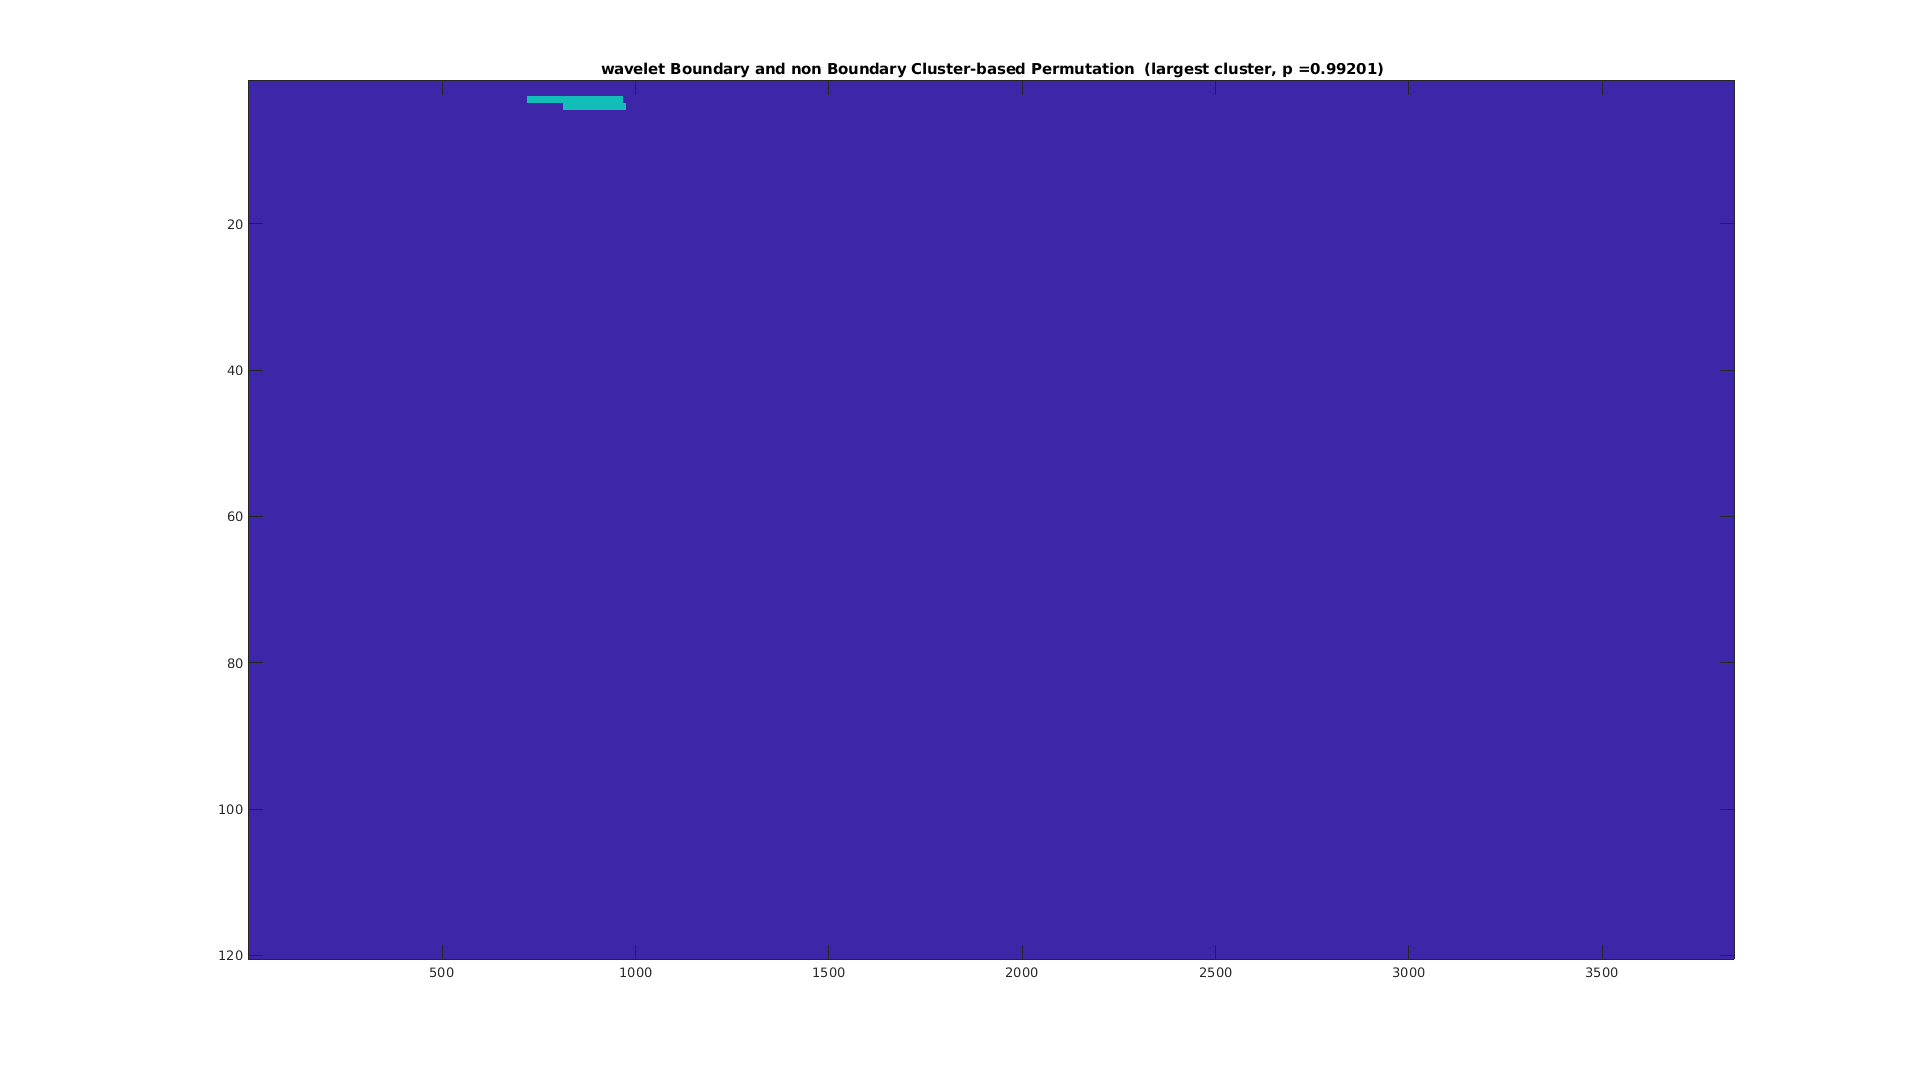

subject='subject1-27 (2turns)';
data_bd = [];
data_non_bd = [];
subjects =wavelet_subject.subjects;
for subi=1:length(subjects)
    data_bd(:,:,subi) = mean(cell2matrix(wavelet_subject.data_bd(subjects(subi),7:18)),3);
    data_non_bd(:,:,subi) = mean(cell2matrix(wavelet_subject.data_non_bd(subjects(subi),7:18)),3);
end
wavelet_porr_h = [];
for i = 1:size(data_bd,1)
    for j = 1:size(data_bd,2)
         [wavelet_porr_h(i,j),~] = ttest(squeeze(data_bd(i,j,:)),squeeze(data_non_bd(i,j,:)));
    end
end
plt_wavelet_region_bd(data_bd, data_non_bd, subject, plot_window) 

#### 3 turns

subject='subject1-27 (3turns)'

subject = 'subject1-27 (3turns)'

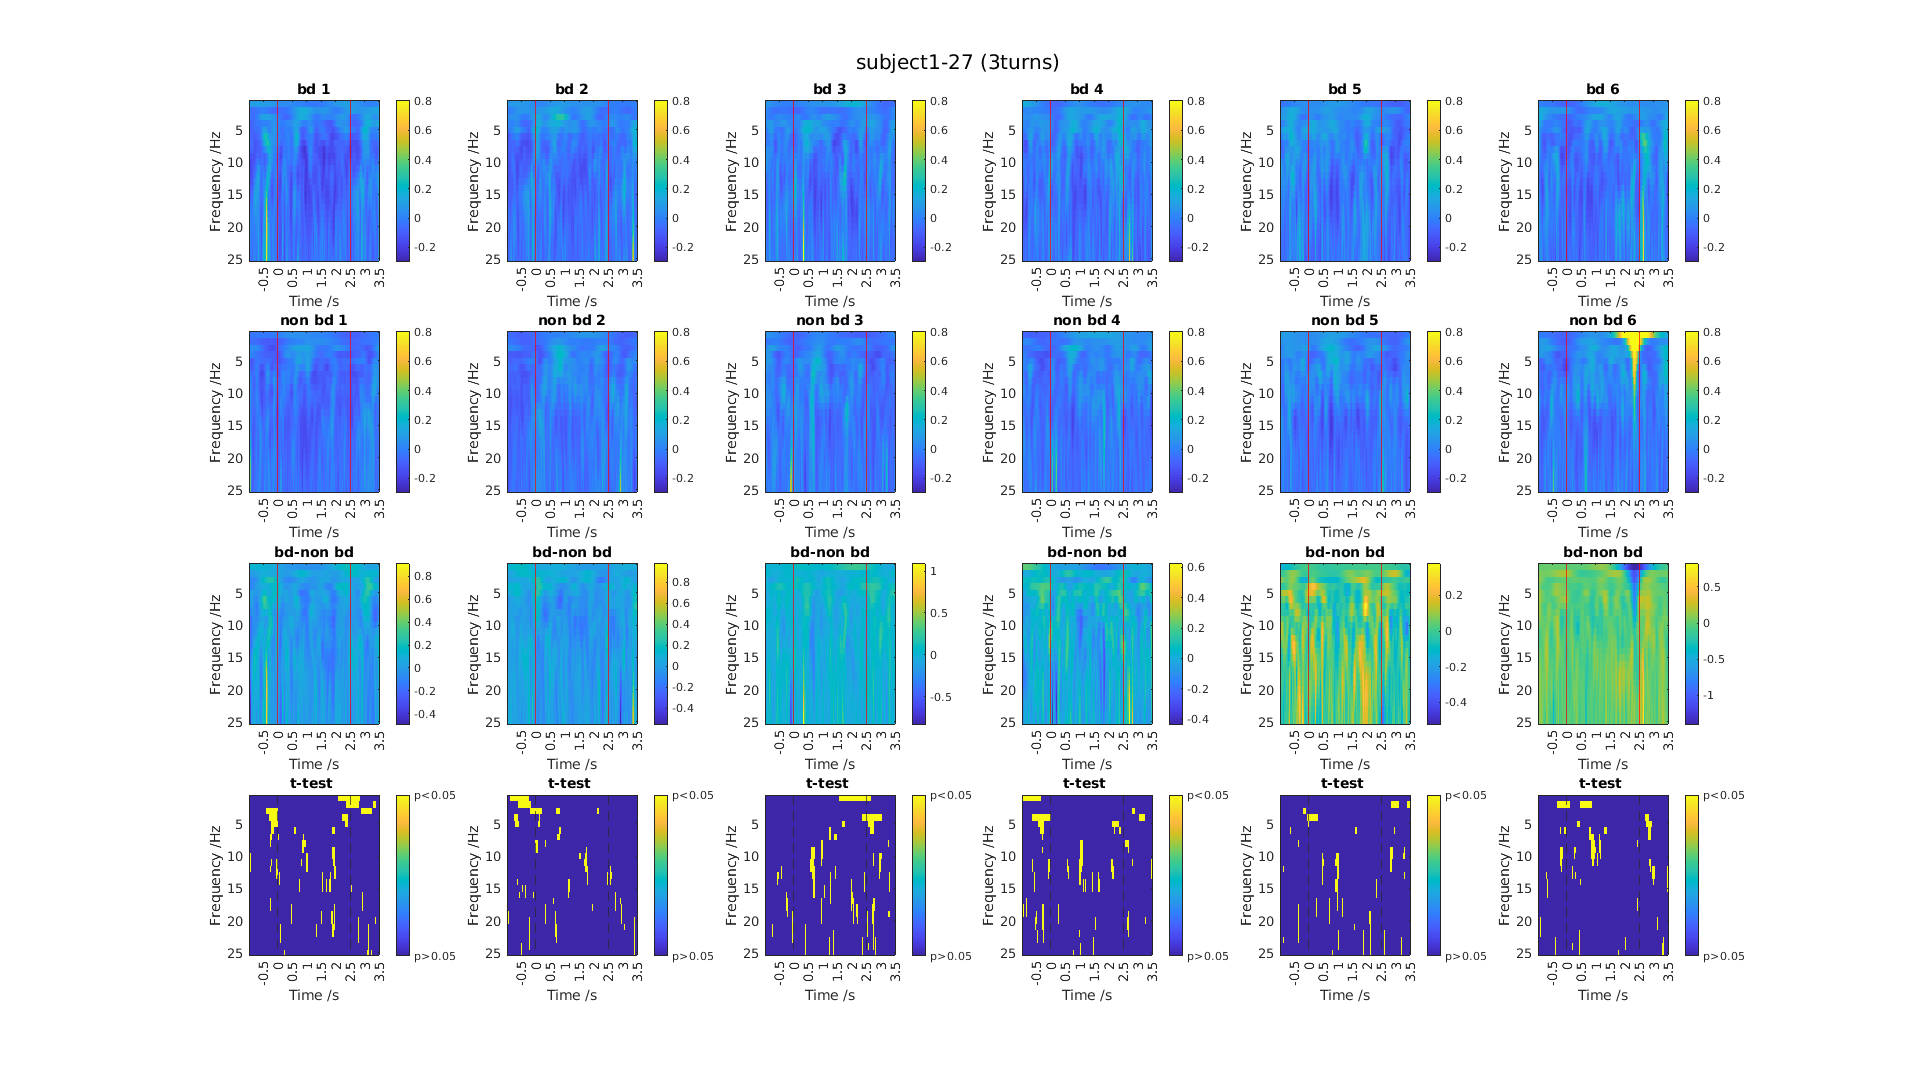

data_bd = [];
data_non_bd = [];
subjects =wavelet_subject.subjects;
for subi=1:length(subjects)
    for seqi=1:6
    data_bd{subi,seqi} = mean(cell2matrix(wavelet_subject.data_bd(subjects(subi),seqi:6:18)),3);
    data_non_bd{subi,seqi} = mean(cell2matrix(wavelet_subject.data_non_bd(subjects(subi),seqi:6:18)),3);
    end
end
plt_wavelet_sd(data_bd, data_non_bd, subject, plot_window)

#### 2 turns

% zoom in 1-25Hz
subject='subject1-27 (2turn)'

subject = 'subject1-27 (2turn)'

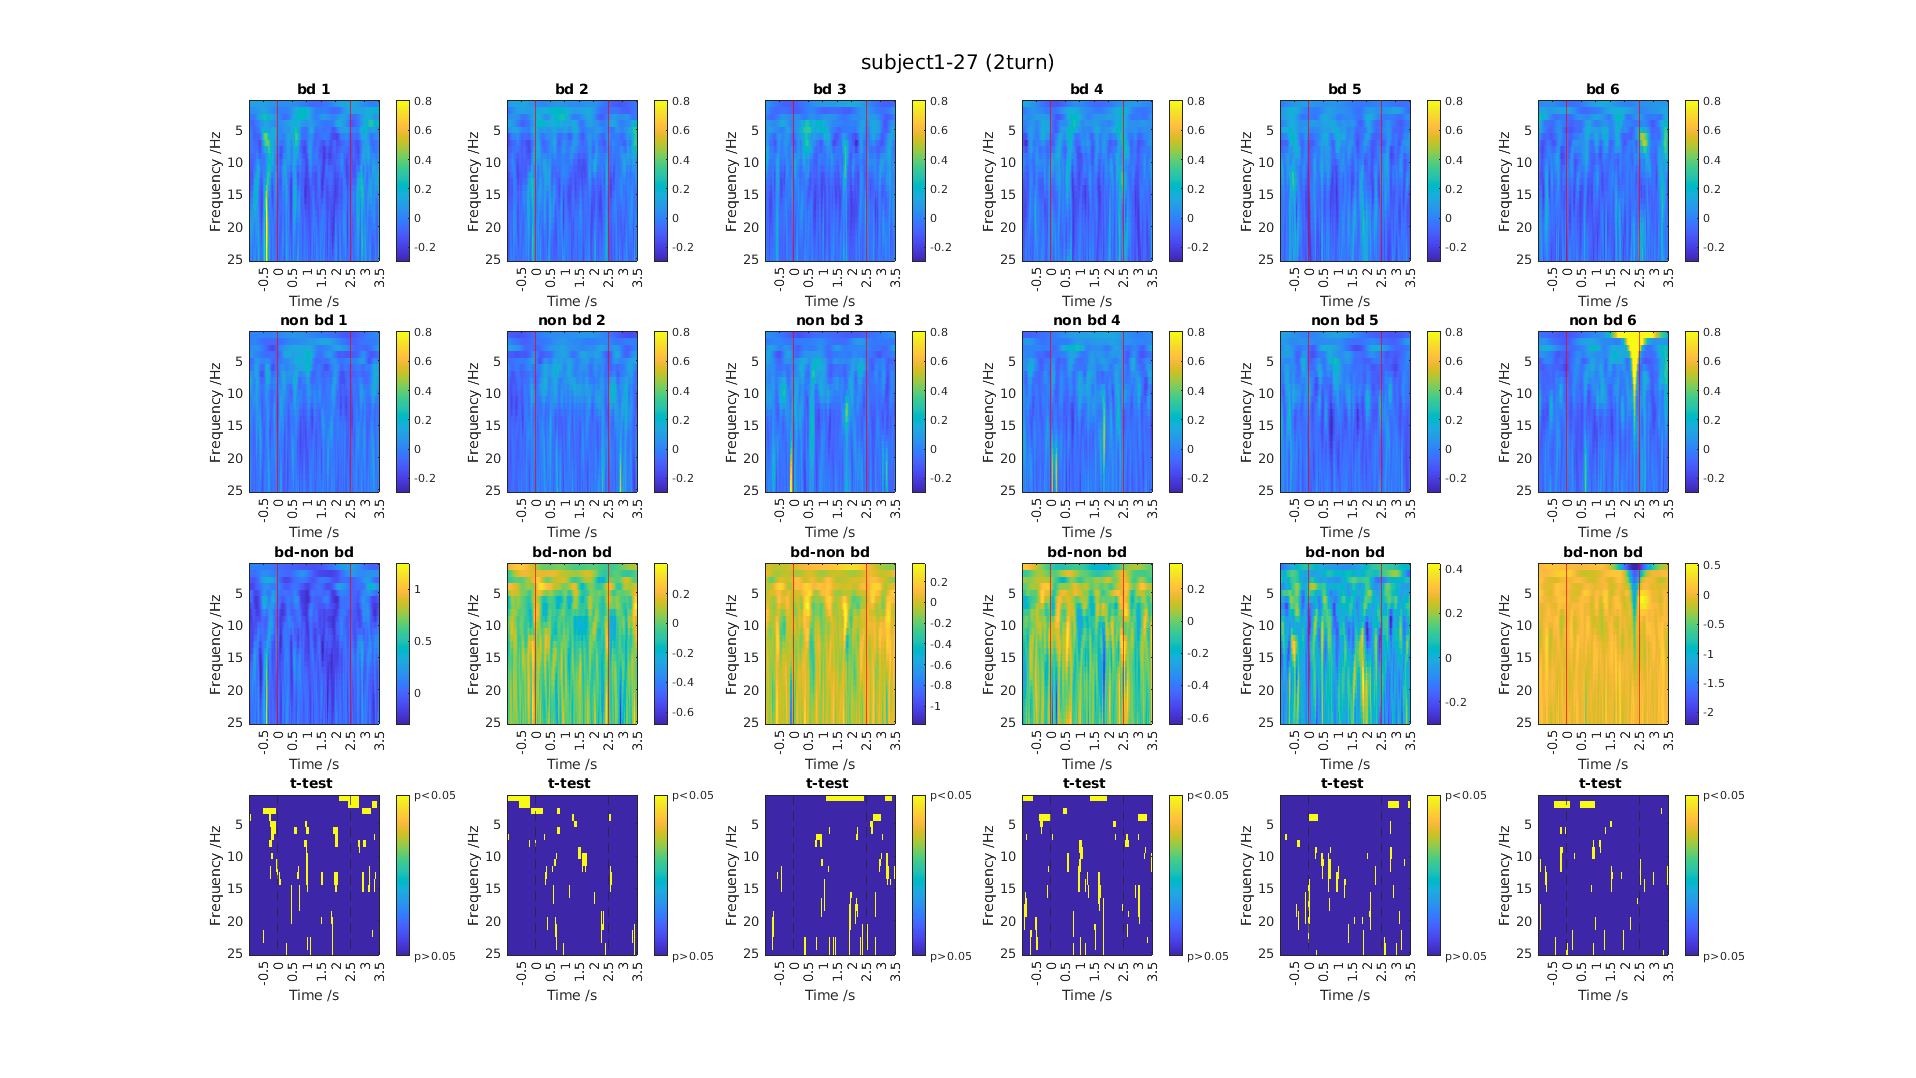

data_bd = [];
data_non_bd = [];
subjects =wavelet_subject.subjects;
for subi=1:length(subjects)
    for seqi=1:6
    data_bd{subi,seqi} = mean(cell2matrix(wavelet_subject.data_bd(subjects(subi),seqi+6:6:18)),3);
    data_non_bd{subi,seqi} = mean(cell2matrix(wavelet_subject.data_non_bd(subjects(subi),seqi+6:6:18)),3);
    end
end
plt_wavelet_sd(data_bd, data_non_bd, subject, plot_window)    

## Theta (anova)

% anovan
wavelet_bd = (cell2matrix(wavelet_subject.data_bd(:,7))+cell2matrix(wavelet_subject.data_bd(:,13)))/2;
wavelet_pre_bd = (cell2matrix(wavelet_subject.data_bd(:,6))+cell2matrix(wavelet_subject.data_bd(:,12)))/2;
wavelet_non_bd = (cell2matrix(wavelet_subject.data_non_bd(:,7))+cell2matrix(wavelet_subject.data_non_bd(:,13)))/2;
wavelet_pre_non_bd = (cell2matrix(wavelet_subject.data_non_bd(:,6))+cell2matrix(wavelet_subject.data_non_bd(:,12)))/2;

wavelet = cat(3, wavelet_bd,wavelet_pre_bd,wavelet_non_bd,wavelet_pre_non_bd);
condition  = reshape(repmat([1,1,2,2], 10, 1),[],1);
position  = reshape(repmat([1,2,1,2], 10, 1),[],1);
p2=[];
for i = 1:size(wavelet,1)
    for j=1:size(wavelet,2)
        p2(i,j,:) = anovan(squeeze(wavelet(i,j,:)),{condition position},'model','interaction','varnames',{'condition','position'},'display','off');
    end
end

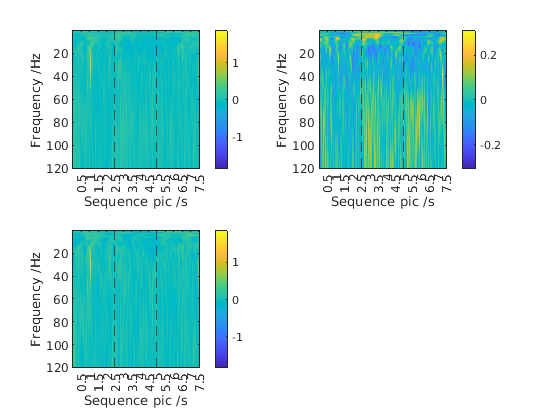

% ttest
data_bd = [];
data_non_bd = [];
subjects =wavelet_subject.subjects;
for subi=1:length(subjects)
    wavelet_bd(:,:,subi) = mean(cell2matrix(wavelet_subject.data_bd(subjects(subi),[7,13])),3);
    wavelet_non_bd(:,:,subi) = mean(cell2matrix(wavelet_subject.data_non_bd(subjects(subi),[7,13])),3);
end

figure
subplot(1,2,1)
imagesc(mean(wavelet_bd,3))
caxis([-0.4,0.4])
yticks(0:20:120);
        yticklabels([0:20:120]);
        ylabel('Frequency /Hz');
        xticks(0:256:7.5*512);
        xticklabels([0:256:7.5*512]/512);
        xlabel('Sequence pic /s')
        xline(2.5*512,'--')
        xline(5*512,'--')
        colorbar()
colorbar()
subplot(1,2,2)
imagesc(mean(wavelet_non_bd,3))
caxis([-0.4,0.4])
yticks(0:20:120);
        yticklabels([0:20:120]);
        ylabel('Frequency /Hz');
        xticks(0:256:7.5*512);
        xticklabels([0:256:7.5*512]/512);
        xlabel('Sequence pic /s')
        xline(2.5*512,'--')
        xline(5*512,'--')
        colorbar()
colorbar()
plt_rsa_sd(wavelet_bd,wavelet_non_bd,'wavelet')

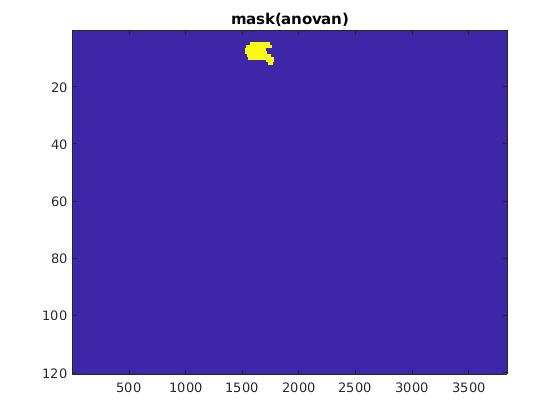

% mask combain  and anova
p=p2;
a = p; a(a<0.05)=-1; a(a>=0.05)=0; a=abs(a);
anova_condition = a(:,:,1);
CC = bwconncomp(anova_condition);
cc_size=[];
for i=1:length(CC.PixelIdxList)
    cc_size(i)=length(CC.PixelIdxList{1, i});
end
[cc_sort,cc_idx] = sort(cc_size,'descend');
mask = zeros(size(anova_condition));
mask(CC.PixelIdxList{1, cc_idx(1)}) = 1;
figure;imagesc(mask)
title('mask(anovan)')

mask_anova2 = mask;

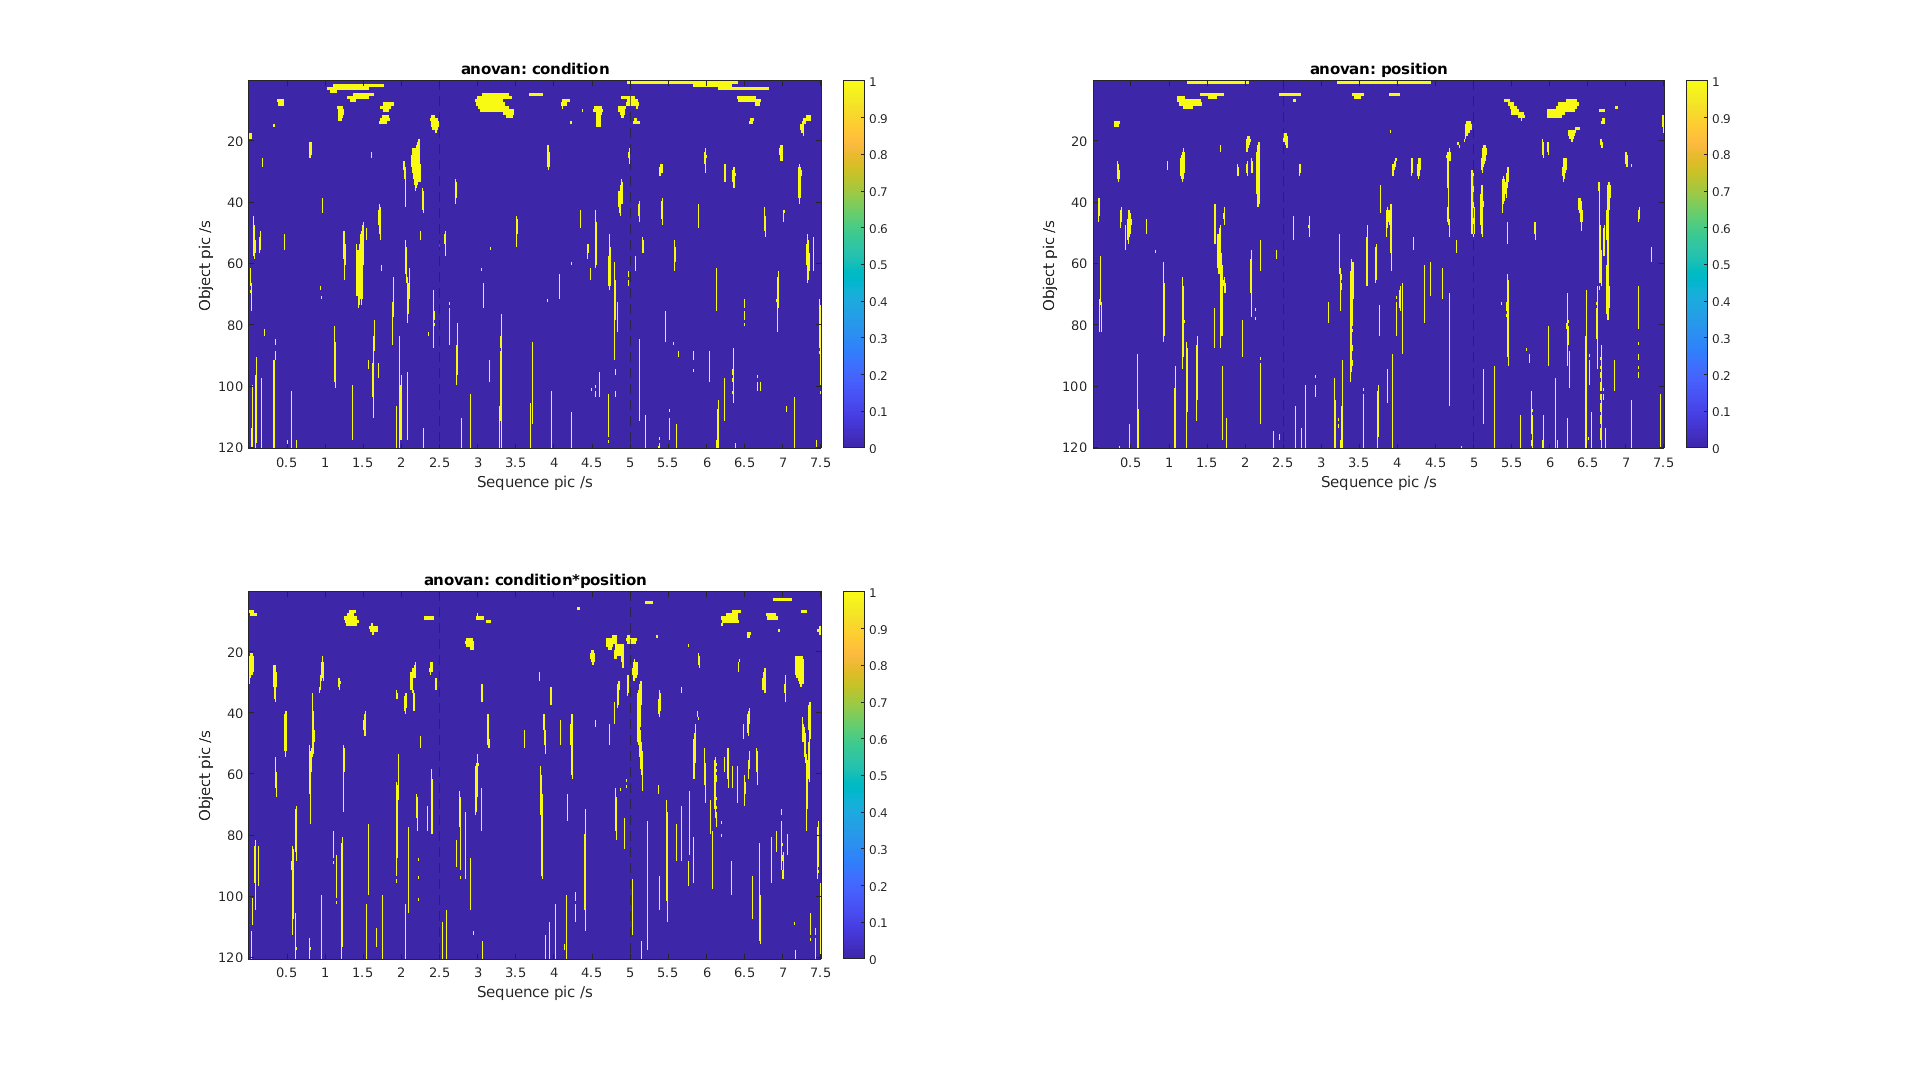

p=p2;
a = p; a(a<0.05)=-1; a(a>=0.05)=0; a=abs(a);
anovan_name = {'condition','position','condition*position'};
figure
for i= 1:3
    subplot(2,2,i)
    if i<4
        imagesc(a(:,:,i))
        title(['anovan: ',anovan_name{i}])
    else
        imagesc(pic_corr_h)
        title('Mask')
    end
    yticks(0:20:120);
    yticklabels([0:20:120]);
    ylabel('Object pic /s')
    xticks(0:256:7.5*512);
    xticklabels([0:256:7.5*512]/512);
    xlabel('Sequence pic /s')
    xline(2.5*512,'--')
    xline(5*512,'--')
    colorbar()
end
set(gcf, 'Position', [1 25 1920 1080]);

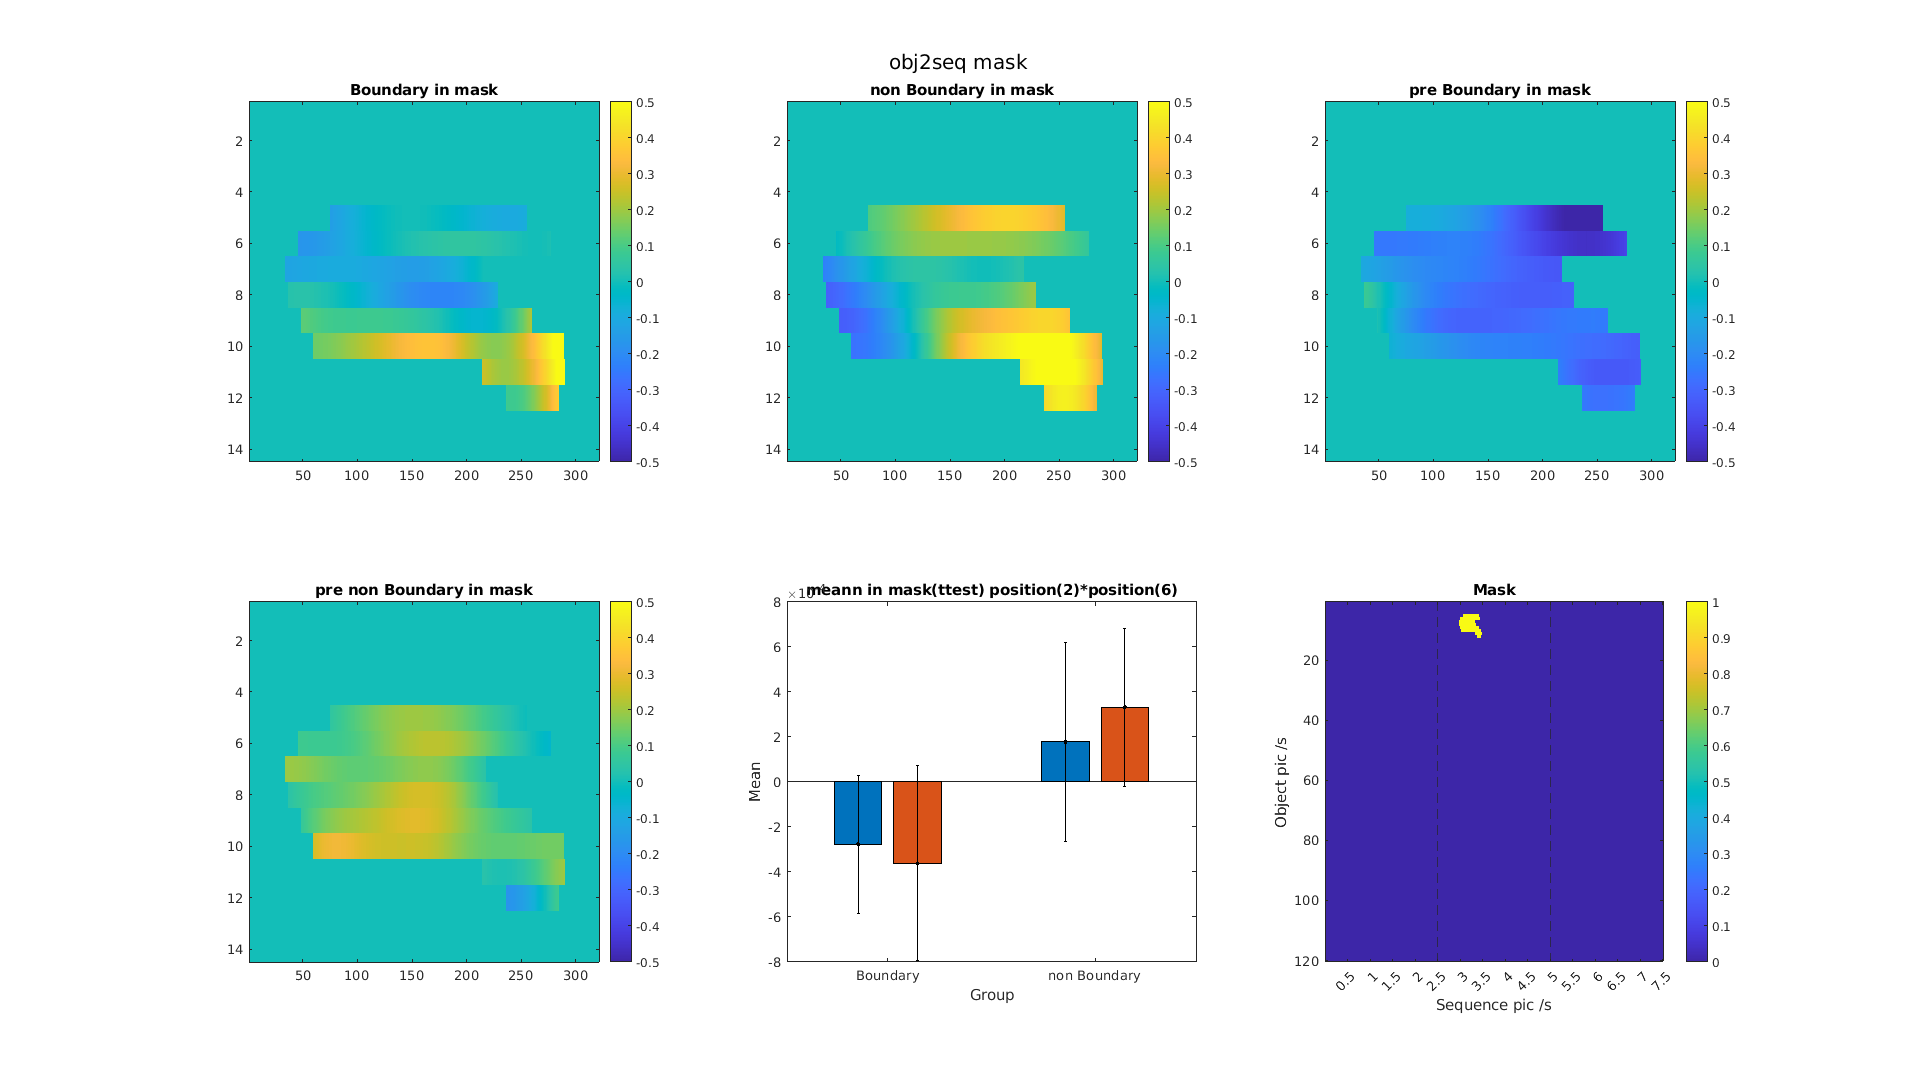

% plot anova result condition(anova 2*2, mask ttest)
mask_anova=mask_anova2;
data = [];
data(1,1,:) = squeeze(mean(mean(wavelet_bd.*mask_anova,1),2));
data(1,2,:) = squeeze(mean(mean(wavelet_pre_bd.*mask_anova,1),2));
data(2,1,:) = squeeze(mean(mean(wavelet_non_bd.*mask_anova,1),2));
data(2,2,:) = squeeze(mean(mean(wavelet_pre_non_bd.*mask_anova,1),2));

figure
clim = [-0.5,0.5];
subplot(2,3,1)
temp = wavelet_bd.*mask_anova;
imagesc(mean(temp(1:14,1490:1810),3))
title('Boundary in mask')
caxis(clim)
colorbar()
subplot(2,3,2)
temp = wavelet_non_bd.*mask_anova;
imagesc(mean(temp(1:14,1490:1810),3))
title('non Boundary in mask')
caxis(clim)
colorbar()
subplot(2,3,3)
temp = wavelet_pre_bd.*mask_anova;
imagesc(mean(temp(1:14,1490:1810),3))
title('pre Boundary in mask')
caxis(clim)
colorbar()
subplot(2,3,4)
temp = wavelet_pre_non_bd.*mask_anova;
imagesc(mean(temp(1:14,1490:1810),3))
title('pre non Boundary in mask')
caxis(clim)
colorbar()
subplot(2,3,5)
plt_bar_group(data,{'Boundary','non Boundary'}) % no ttest for each bins
title('meann in mask(ttest) position(2)*position(6)')
subplot(2,3,6)
imagesc(mask_anova)
title('Mask')
yticks(0:20:120);
yticklabels([0:20:120]);
ylabel('Object pic /s')
xticks(0:256:7.5*512);
xticklabels([0:256:7.5*512]/512);
xlabel('Sequence pic /s')
xline(2.5*512,'--')
xline(5*512,'--')
colorbar()
sgtitle('obj2seq mask')

% permutest all 18 picture


% permutation only 1000 times
tic
[clusters_perm, p_perm, t_sums_perm, permutation_distribution ] = permutest(wavelet_bd,wavelet_non_bd,true,0.05,1000);
toc

Elapsed time is 137.895404 seconds.


% permutest p=0.05
i=1;
mask = NaN(size(data_bd(:,:,1)));
mask(clusters_perm{1, i}) = 1;
figure;plt_imagesc(mask,'wavelet')

ans = 2

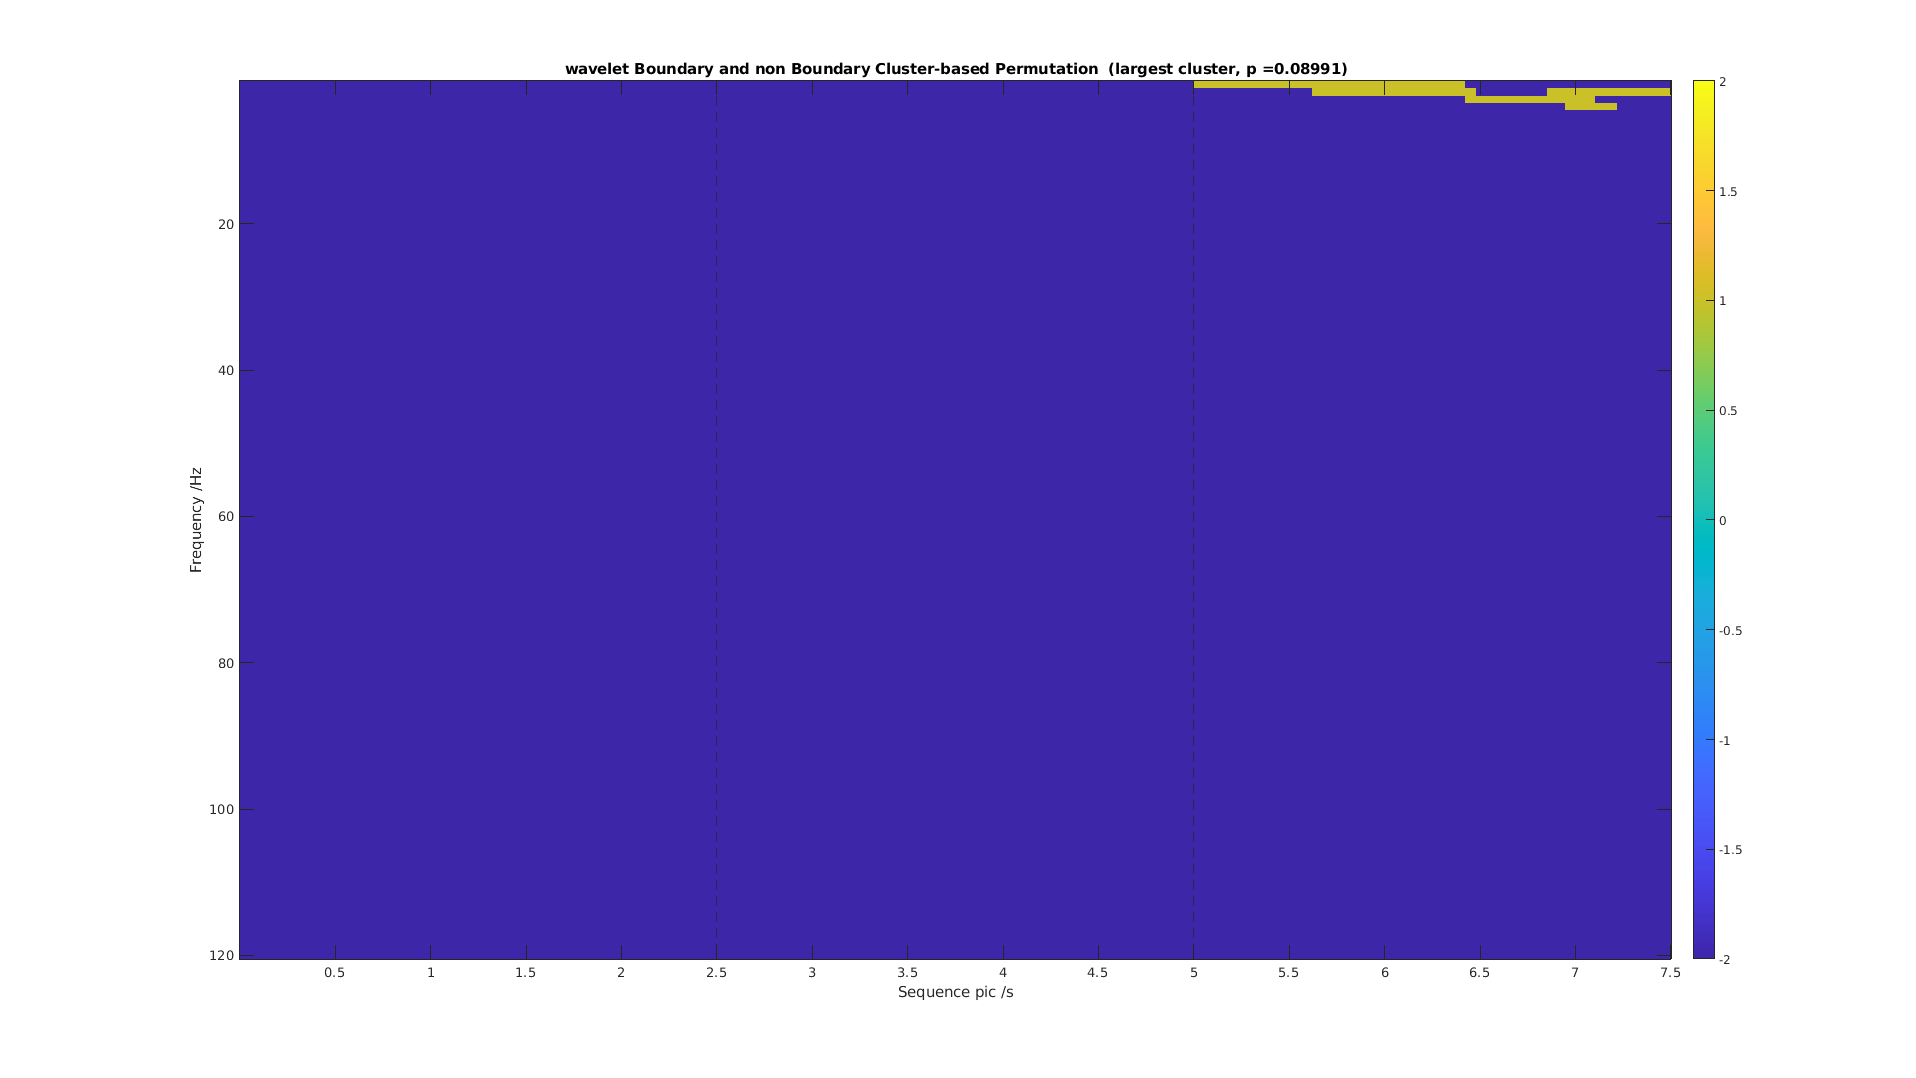

title(['wavelet Boundary and non Boundary Cluster-based Permutation  (largest cluster, p =',num2str(p_perm(i)),')'])
set(gcf, 'Position', [1 25 1920 1080]);

% anova   position(2,[boundary, non_boundary])*position(6,[1:6])
wavelet=[];
for pici =1:6
wavelet = cat(3, wavelet,cell2matrix(wavelet_subject.data_bd(:,[pici,pici+6,pici+12])));
end
for pici =1:6
wavelet = cat(3, wavelet,cell2matrix(wavelet_subject.data_non_bd(:,[pici,pici+6,pici+12])));
end
condition  = reshape(repmat([1,2], 10*6, 1),[],1);
position  = reshape(repmat([1:6,1:6], 10, 1),[],1);
p6=[];
for i = 1:size(wavelet,1)
    for j=1:size(wavelet,2)
        p6(i,j,:) = anovan(squeeze(wavelet(i,j,:)),{condition position},'model','interaction','varnames',{'condition','position'},'display','off');
    end
end

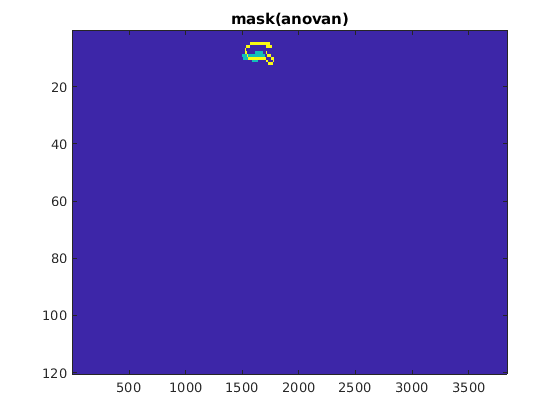

% compare anova mask in 2*2 and 2*6
p=p6;
a = p; a(a<0.05)=-1; a(a>=0.05)=0; a=abs(a);
anova_condition = a(:,:,1);
BW_anova = bwperim(mask_anova2);
CC = bwconncomp(anova_condition);
cc_size=[];
for i=1:length(CC.PixelIdxList)
    cc_size(i)=length(CC.PixelIdxList{1, i});
end
[cc_sort,cc_idx] = sort(cc_size,'descend');
mask = zeros(size(anova_condition));
mask(CC.PixelIdxList{1, cc_idx(6)}) = 1;
figure;imagesc(max(mask,BW_anova*2))
title('mask(anovan)')

mask_anova6 = mask;

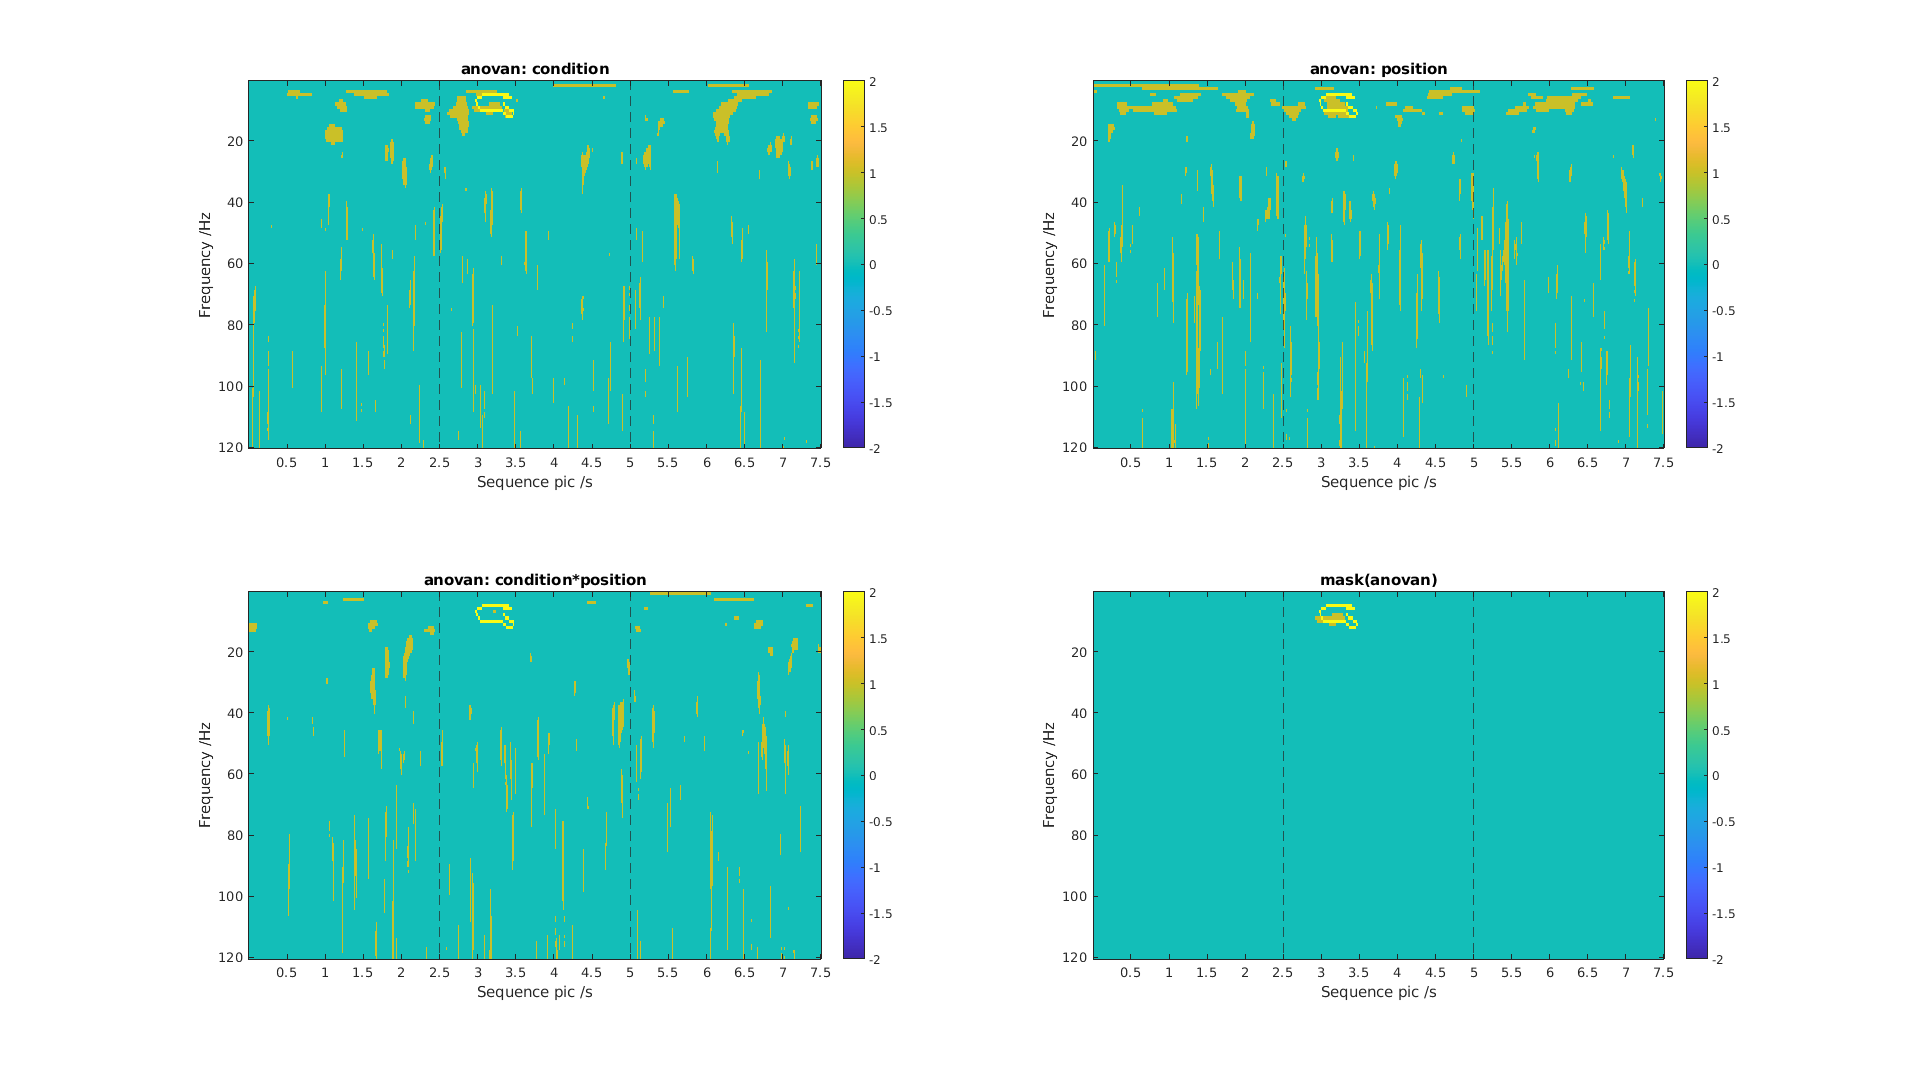

p=p6;
a = p; a(a<0.05)=-1; a(a>=0.05)=0; a=abs(a);
anovan_name = {'condition','position','condition*position'};
figure
for i= 1:4
    subplot(2,2,i)
    if i<4
          plt_imagesc(max(a(:,:,i),BW_anova*2),'wavelet');
          title(['anovan: ',anovan_name{i}])
    else
        plt_imagesc(max(mask_anova6,BW_anova*2),'wavelet');
        title('mask(anovan)')
    end
end
set(gcf, 'Position', [1 25 1920 1080]);

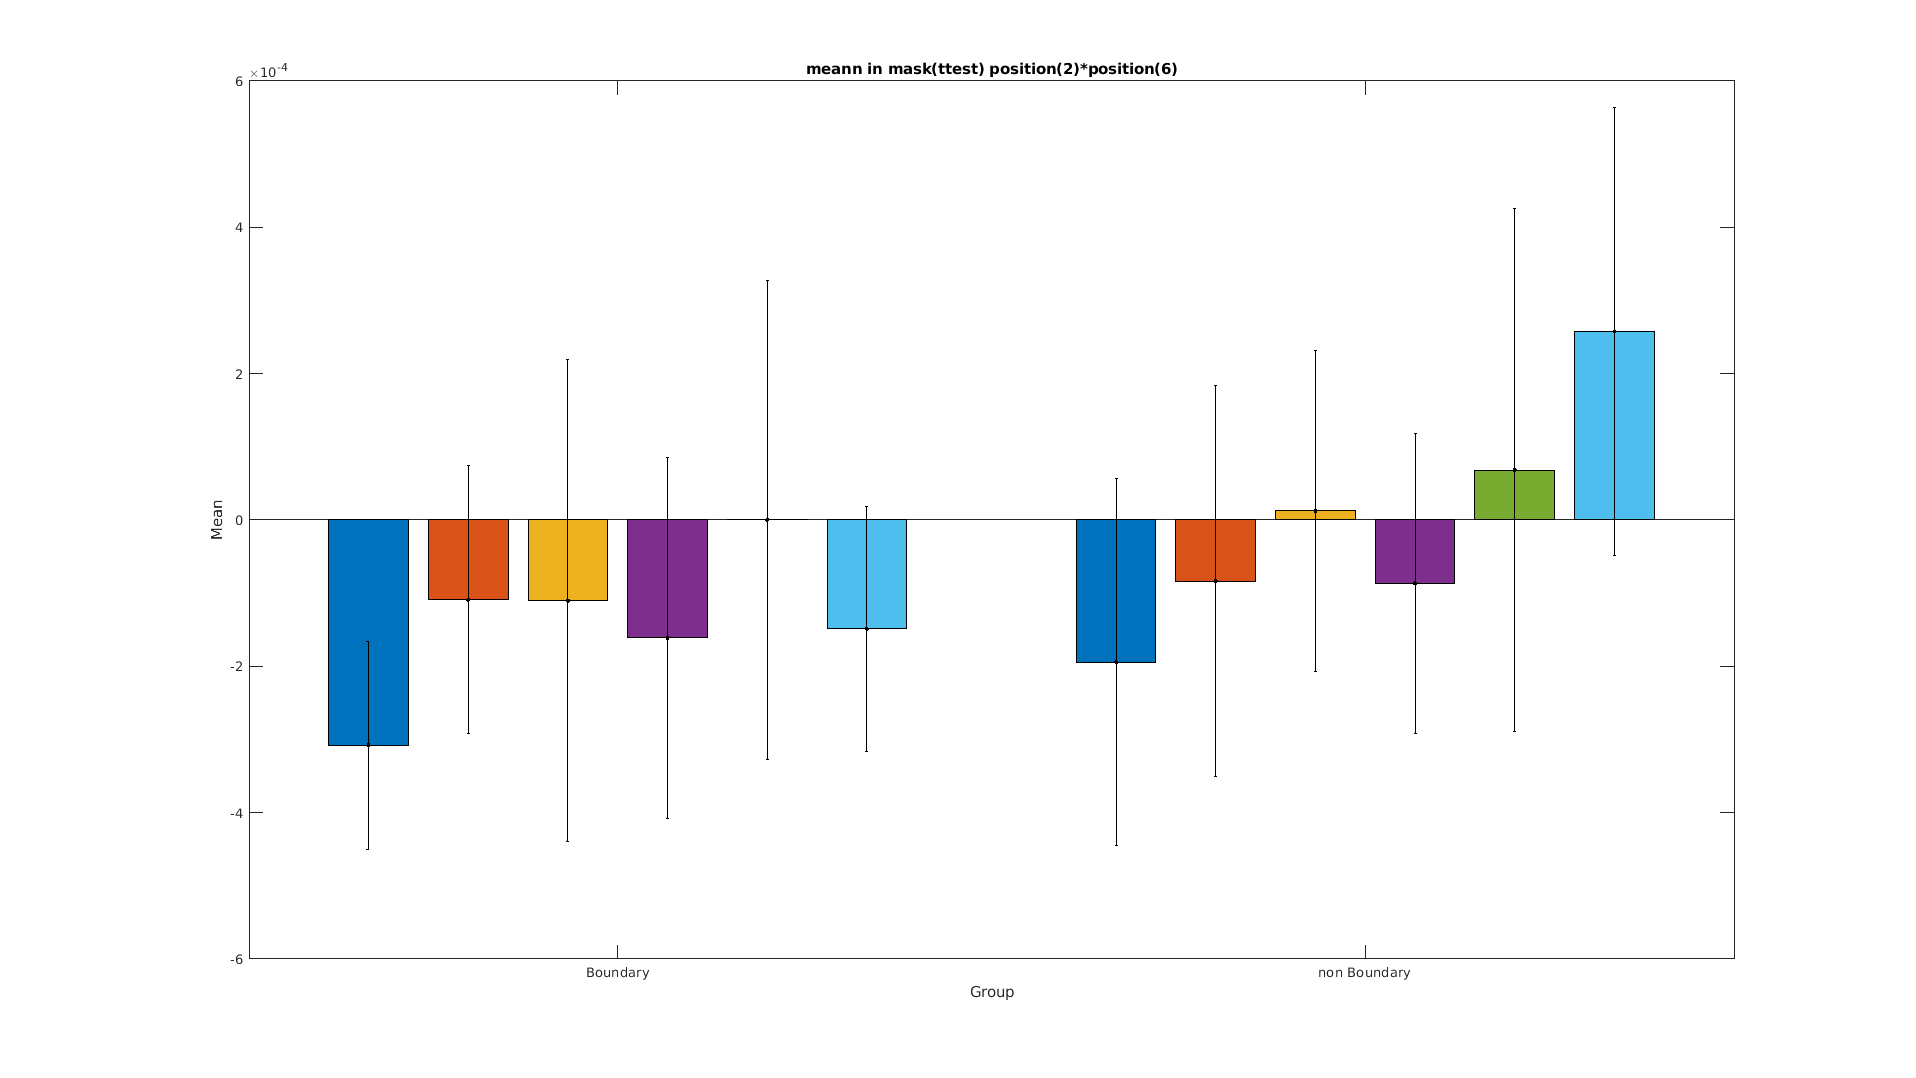

% plot anova result condition(anova 2*6, mask ttest)
data = [];
for pici=1:6
    data(1,pici,:) = squeeze(mean(mean(cell2matrix(wavelet_subject.data_bd(:,[pici,pici+6,pici+12])).*mask_anova6,1),2));
    data(2,pici,:) = squeeze(mean(mean(cell2matrix(wavelet_subject.data_non_bd(:,[pici,pici+6,pici+12])).*mask_anova6,1),2));
end
figure
plt_bar_group(data,{'Boundary','non Boundary'}) % no ttest for each bins
title('meann in mask(ttest) position(2)*position(6)')